# MA 423 Matrix Computations                    Lab - 1

## Name: Rasesh Srivastava

## Roll number: 210123072

format long e

## Question 1

Part (a)

W = Wilkinson(5)

W =      1     0     0     0     1
    -1     1     0     0     1
    -1    -1     1     0     1
    -1    -1    -1     1     1
    -1    -1    -1    -1     1


Part (b)

H = Hamiltonian(2)

H =      5.376671395461000e-01     1.833885014595086e+00     3.187652398589808e-01    -1.307688296305273e+00
     1.833885014595086e+00     8.621733203681206e-01    -1.307688296305273e+00     3.426244665386499e-01
     3.187652398589808e-01    -1.307688296305273e+00    -5.376671395461000e-01    -1.833885014595086e+00
    -1.307688296305273e+00     3.426244665386499e-01    -1.833885014595086e+00    -8.621733203681206e-01


## Question 2

A = rand(8);
disp(A);

     9.575068354342976e-01     4.217612826262750e-01     6.787351548577735e-01     2.769229849608900e-01     4.387443596563982e-01     7.093648308580726e-01     9.597439585160811e-01     8.909032525357985e-01
     9.648885351992765e-01     9.157355251890671e-01     7.577401305783334e-01     4.617139063115394e-02     3.815584570930084e-01     7.546866819823609e-01     3.403857266661332e-01     9.592914252054443e-01
     1.576130816775483e-01     7.922073295595544e-01     7.431324681249162e-01     9.713178123584754e-02     7.655167881490024e-01     2.760250769985784e-01     5.852677509797773e-01     5.472155299638031e-01
     9.705927817606157e-01     9.594924263929030e-01     3.922270195341682e-01     8.234578283272926e-01     7.951999011370632e-01     6.797026768536748e-01     2.238119394911370e-01     1.386244428286791e-01
     9.571669482429456e-01     6.557406991565868e-01     6.554778901775566e-01     6.948286229758170e-01     1.868726045543786e-01     6.550980039738407e-01     7.5

a) Maximum value of each column

disp(max(A));

     9.705927817606157e-01     9.594924263929030e-01     7.577401305783334e-01     9.502220488383549e-01     7.951999011370632e-01     7.546866819823609e-01     9.597439585160811e-01     9.592914252054443e-01



b) Maximum value of each row

disp(max(A'));

     9.597439585160811e-01     9.648885351992765e-01     7.922073295595544e-01     9.705927817606157e-01     9.571669482429456e-01     4.897643957882311e-01     9.502220488383549e-01     9.339932477575505e-01



disp(max(A')');

     9.597439585160811e-01
     9.648885351992765e-01
     7.922073295595544e-01
     9.705927817606157e-01
     9.571669482429456e-01
     4.897643957882311e-01
     9.502220488383549e-01
     9.339932477575505e-01



disp(max(A,[],2));

     9.597439585160811e-01
     9.648885351992765e-01
     7.922073295595544e-01
     9.705927817606157e-01
     9.571669482429456e-01
     4.897643957882311e-01
     9.502220488383549e-01
     9.339932477575505e-01



c) Overall Maximum value in A

disp(max(max(A)));

     9.705927817606157e-01



 Row and column indices of all elements that are larger than 0.25

B = A > 0.25;
disp(B);

   1   1   1   1   1   1   1   1
   1   1   1   0   1   1   1   1
   0   1   1   0   1   1   1   1
   1   1   1   1   1   1   0   0
   1   1   1   1   0   1   1   0
   1   0   0   1   1   0   1   1
   1   1   1   1   1   0   1   1
   0   1   0   0   1   1   1   1



 Row and column indices of all elements that are larger than 0.25

[r,c] = find(B);
for i = 1:length(r)
    fprintf('(%d, %d), ', r(i), c(i));
end

(1, 1), (2, 1), (4, 1), (5, 1), (6, 1), (7, 1), (1, 2), (2, 2), (3, 2), (4, 2), (5, 2), (7, 2), (8, 2), (1, 3), (2, 3), (3, 3), (4, 3), (5, 3), (7, 3), (1, 4), (4, 4), (5, 4), (6, 4), (7, 4), (1, 5), (2, 5), (3, 5), (4, 5), (6, 5), (7, 5), (8, 5), (1, 6), (2, 6), (3, 6), (4, 6), (5, 6), (8, 6), (1, 7), (2, 7), (3, 7), (5, 7), (6, 7), (7, 7), (8, 7), (1, 8), (2, 8), (3, 8), (6, 8), (7, 8), (8, 8), 

## Question 3

**With n = 5,**

n = 5;
A = magic(n);
disp(A);

    17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9



 Checking whether the row, column, diagonal and antidiagonal sums are identical or not.

disp(sum(A));

    65    65    65    65    65



disp(sum(A'));

    65    65    65    65    65



disp(min(sum(A)) == max(sum(A)));

   1



disp(min(sum(A,2)) == max(sum(A,2)));

   1



disp(sum(diag(A)) == max(sum(A,2)));

   1



disp(sum(diag(A)) == sum(diag(flipud(A))));

   1



**With n = 4,**

n = 4;
A = magic(n);
disp(A);

    16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1



 Checking whether the row, column, diagonal and antidiagonal sums are identical or not.

disp(sum(A));

    34    34    34    34



disp(sum(A'));

    34    34    34    34



disp(min(sum(A)) == max(sum(A)));

   1



disp(min(sum(A,2)) == max(sum(A,2)));

   1



disp(sum(diag(A)) == max(sum(A,2)));

   1



disp(sum(diag(A)) == sum(diag(flipud(A))));

   1



## Question 4

a)

`sum(A)`

The `sum(A)` function computes the sum of each column of the matrix A.

`sum(A')'`

The expression `sum(A')'` computes the sum of each row of the matrix A.

`sum(diag(A))`

The `sum(diag(A))` function computes the sum of the main diagonal elements of the matrix A.

`sum(diag(flipud(A)))`

The `sum(diag(flipud(A)))` function computes the sum of the anti-diagonal (counter-diagonal) elements of the matrix A.

`rank(A)`

The `rank(A)` function computes the rank of the matrix A. The rank is the maximum number of linearly independent column vectors (or row vectors) in the matrix.

b)

Diagonal and anti-diagonal sums do not remain same after doing p = randperm(n); q = randperm(n); A = A(p,q)

The sum(A), sum(A')' and rank(A) remain the same even after performing these operations on A.

Ans) Yes

for n = 3:5
    fprintf("For n = %d,\n", n)
    A = magic(n);
    % Performing the mentioned operations on A
    p = randperm(n);
    q = randperm(n);
    A = A(p,q);
    fprintf("Sum of columns of A")
    disp(sum(A));
    fprintf("Sum of rows of A")
    disp(sum(A')');
    fprintf("Rank of A")
    disp(rank(A));
    fprintf("Sum of the diagonal elements of A")
    disp(sum(diag(A)))
    fprintf("Sum of the Anti-Diagonal elements of A")
    disp(sum(diag(flipud(A))))
end

For n = 3,


Sum of columns of A

    15    15    15



Sum of rows of A

    15
    15
    15



Rank of A

     3



Sum of the diagonal elements of A

    15



Sum of the Anti-Diagonal elements of A

    18



For n = 4,


Sum of columns of A

    34    34    34    34



Sum of rows of A

    34
    34
    34
    34



Rank of A

     3



Sum of the diagonal elements of A

    54



Sum of the Anti-Diagonal elements of A

    14



For n = 5,


Sum of columns of A

    65    65    65    65    65



Sum of rows of A

    65
    65
    65
    65
    65



Rank of A

     5



Sum of the diagonal elements of A

    60



Sum of the Anti-Diagonal elements of A

    60



For the magic square A = magic(4),

n = 4;
A = magic(n);
disp(null(A));

    -2.236067977499789e-01
    -6.708203932499369e-01
     6.708203932499369e-01
     2.236067977499788e-01



disp(null(A,'r'));

    -1
    -3
     3
     1



disp(null(sym(A)));

$$\left(\begin{array}{c} -1\\ -3\\ 3\\ 1 \end{array}\right)$$

disp(rref(A));

     1     0     0     1
     0     1     0     3
     0     0     1    -3
     0     0     0     0



`null(A)`

The `null` function computes an orthonormal basis for the null space of a matrix. If the null space is non-trivial, it indicates that the columns of the matrix are linearly dependent. For a singular matrix A, `null(A)` will return a non-empty matrix representing the basis vectors of the null space.

`null(A, 'r')`

The `null(..., 'r')` function returns a rational basis for the null space of a matrix. This basis can provide more precise information about the dependencies in terms of rational numbers. This will give the null space in rational form, providing insight into exact dependencies among the columns.

`null(sym(A))`

The `null(sym(...))` function computes the null space of the matrix using symbolic arithmetic, which can be useful for exact analysis. This will return the null space using symbolic computation, which can sometimes reveal more precise relationships.

`rref(A)`

The `rref` function computes the reduced row echelon form (RREF) of a matrix. The RREF can show which columns are pivot columns and which are not, providing direct insight into the linear dependence among columns. The reduced row echelon form shows which columns are pivot columns. Non-pivot columns are linearly dependent on the pivot columns. For a singular matrix, at least one column will not be a pivot column, indicating linear dependence.

## Question 5

a) False

b) True, if A is not singular.

**With n = 3,**

A = magic(3);

disp(A^(-1));

     1.472222222222222e-01    -1.444444444444444e-01     6.388888888888887e-02
    -6.111111111111111e-02     2.222222222222222e-02     1.055555555555556e-01
    -1.944444444444445e-02     1.888888888888889e-01    -1.027777777777778e-01



disp(A.^(-1));

     1.250000000000000e-01     1.000000000000000e+00     1.666666666666667e-01
     3.333333333333333e-01     2.000000000000000e-01     1.428571428571428e-01
     2.500000000000000e-01     1.111111111111111e-01     5.000000000000000e-01



disp(1./A);

     1.250000000000000e-01     1.000000000000000e+00     1.666666666666667e-01
     3.333333333333333e-01     2.000000000000000e-01     1.428571428571428e-01
     2.500000000000000e-01     1.111111111111111e-01     5.000000000000000e-01



disp(A^(-1) == 1./A);

   0   0   0
   0   0   0
   0   0   0



disp(A.^(-1) == 1./A);

   1   1   1
   1   1   1
   1   1   1



**With n = 4,**

A = magic(4);

disp(A^(-1));

     9.382499223688541e+13     2.814749767106559e+14    -2.814749767106560e+14    -9.382499223688527e+13
     2.814749767106559e+14     8.444249301319679e+14    -8.444249301319678e+14    -2.814749767106558e+14
    -2.814749767106559e+14    -8.444249301319679e+14     8.444249301319678e+14     2.814749767106559e+14
    -9.382499223688534e+13    -2.814749767106559e+14     2.814749767106560e+14     9.382499223688523e+13



disp(A.^(-1));

     6.250000000000000e-02     5.000000000000000e-01     3.333333333333333e-01     7.692307692307693e-02
     2.000000000000000e-01     9.090909090909091e-02     1.000000000000000e-01     1.250000000000000e-01
     1.111111111111111e-01     1.428571428571428e-01     1.666666666666667e-01     8.333333333333333e-02
     2.500000000000000e-01     7.142857142857142e-02     6.666666666666667e-02     1.000000000000000e+00



disp(1./A);

     6.250000000000000e-02     5.000000000000000e-01     3.333333333333333e-01     7.692307692307693e-02
     2.000000000000000e-01     9.090909090909091e-02     1.000000000000000e-01     1.250000000000000e-01
     1.111111111111111e-01     1.428571428571428e-01     1.666666666666667e-01     8.333333333333333e-02
     2.500000000000000e-01     7.142857142857142e-02     6.666666666666667e-02     1.000000000000000e+00



disp(A^(-1) == 1./A);

   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0



disp(A.^(-1) == 1./A);

   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1



## Question 6

Ans) Differentiation

Example: Let the polynomial be q(x) = 5x^3 + 7x^2 + 4x + 6

p = [5, 7, 4, 6];
coefficients_of_differentiated_polynomial = (length(p)-1:-1:0) .* p

coefficients_of_differentiated_polynomial =     15    14     4     0


q'(x) = 15x^2 + 14x + 4 + 0

## Question 7

a) Using diag to build the 16-by-16 matrix A

A = -2*eye(16);
A = A + diag(ones(15,1),1);
A = A + diag(ones(15,1),-1);
A = A + diag(1,15) + diag(1,-15);
disp(A);

    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0
     0     0     0     0     0

b) Using toeplitz to build the 16-by-16 matrix A

a = zeros(16,0);
a(1) = -2; a(2) = 1; a(16)=1;
A = toeplitz(a);
disp(A);

    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0
     0     0     0     0     0

c) Building the 2 matrices using toeplitz and other things

a = 1:1:8;
b = zeros(1,8);
b(1)=1;

Built the 1st Matrix A

A = toeplitz(b,a); % b as the first column
disp(A);

     1     2     3     4     5     6     7     8
     0     1     2     3     4     5     6     7
     0     0     1     2     3     4     5     6
     0     0     0     1     2     3     4     5
     0     0     0     0     1     2     3     4
     0     0     0     0     0     1     2     3
     0     0     0     0     0     0     1     2
     0     0     0     0     0     0     0     1



Building the 2nd Matrix given in the question in part c)

A = toeplitz(a);
% one way of solution
A = 1./A;
disp(A);   % The required Matrix

     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01     1.428571428571428e-01     1.250000000000000e-01
     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01     1.428571428571428e-01
     3.333333333333333e-01     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01
     2.500000000000000e-01     3.333333333333333e-01     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01
     2.000000000000000e-01     2.500000000000000e-01     3.333333333333333e-01     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.3

% Another way of solution: using triu
A = triu(A);
a = 1./a;
disp(a);    % The required Matrix

     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01     1.428571428571428e-01     1.250000000000000e-01



Built the 2nd Matrix A

A = toeplitz(a);
disp(A);        % The required Matrix

     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01     1.428571428571428e-01     1.250000000000000e-01
     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01     1.428571428571428e-01
     3.333333333333333e-01     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01     1.666666666666667e-01
     2.500000000000000e-01     3.333333333333333e-01     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01
     2.000000000000000e-01     2.500000000000000e-01     3.333333333333333e-01     5.000000000000000e-01     1.000000000000000e+00     5.000000000000000e-01     3.3

disp(sym(A));   % Printing the Matrix in a nice format

$$\left(\begin{array}{cccccccc} 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8}\\ \frac{1}{2} & 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7}\\ \frac{1}{3} & \frac{1}{2} & 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6}\\ \frac{1}{4} & \frac{1}{3} & \frac{1}{2} & 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5}\\ \frac{1}{5} & \frac{1}{4} & \frac{1}{3} & \frac{1}{2} & 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4}\\ \frac{1}{6} & \frac{1}{5} & \frac{1}{4} & \frac{1}{3} & \frac{1}{2} & 1 & \frac{1}{2} & \frac{1}{3}\\ \frac{1}{7} & \frac{1}{6} & \frac{1}{5} & \frac{1}{4} & \frac{1}{3} & \frac{1}{2} & 1 & \frac{1}{2}\\ \frac{1}{8} & \frac{1}{7} & \frac{1}{6} & \frac{1}{5} & \frac{1}{4} & \frac{1}{3} & \frac{1}{2} & 1 \end{array}\right)$$

Using format rat for the 2nd Matrix

[N, D] = rat(A)

N =      1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1


D =      1     2     3     4     5     6     7     8
     2     1     2     3     4     5     6     7
     3     2     1     2     3     4     5     6
     4     3     2     1     2     3     4     5
     5     4     3     2     1     2     3     4
     6     5     4     3     2     1     2     3
     7     6     5     4     3     2     1     2
     8     7     6     5     4     3     2     1


## Question 8

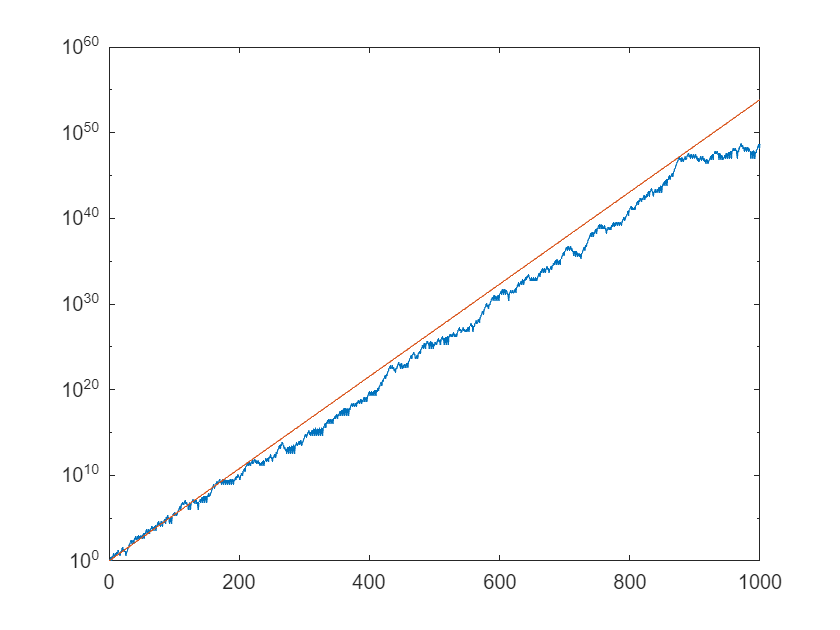

rng(1000,'twister')
x = [1 2];
for n=2:999
    x(n+1) = x(n)+sign(rand-0.5)*x(n-1);
end
figure;
semilogy(1:1000,abs(x));
c = 1.13198824;
hold on;
semilogy(1:1000,c.^[1:1000]);
hold off;

## Question 9

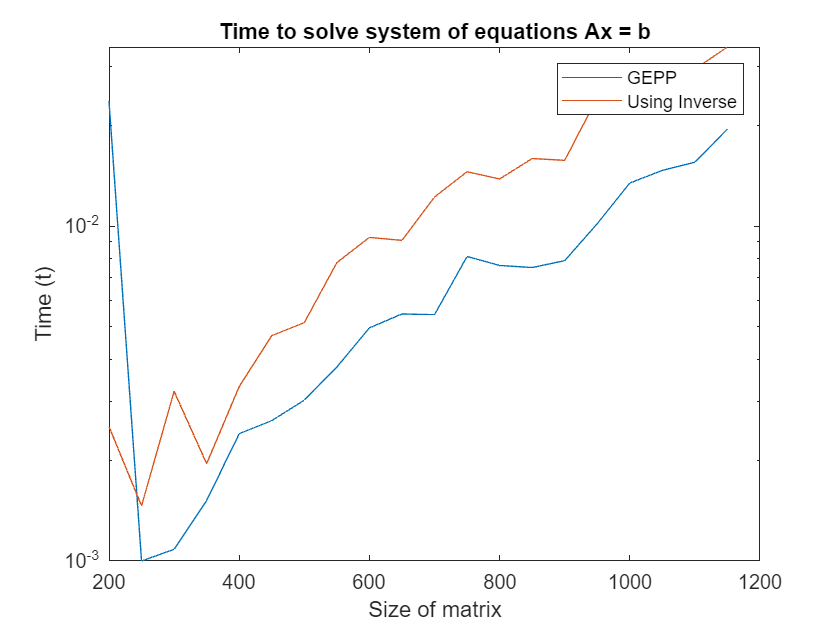

% clear;
m = (200: 50: 1150);
time1 = (1: 20);
time2 = (1: 20);

for i = 1: 20
    A = rand(m(i));
    b = rand(m(i), 1);

    tic;
    x = A\b;
    time1(i) = toc;

    tic;
    x = inv(A) * b;
    time2(i) = toc;
end
figure;
semilogy(m, time1, m, time2);
title("Time to solve system of equations Ax = b")
legend("GEPP", "Using Inverse");
xlabel("Size of matrix");
ylabel("Time (t)");
hold off;

# Function Programs

## Question 1 Part (a)

Function to generate and return Wilkinson matrix of size n with n being the input parameter

function W = Wilkinson(n)
    A = eye(n);
    B = tril(-ones(n),-1);
    W = A + B;
    W(:, n) = 1;
end

## Question 1 Part (b)

Function to generate and return a random Hamiltonian matrix of size 2n * 2n with n being the input parameter

function H = Hamiltonian(n)
    n = 2 * n;
    H11 = randn(floor(n/2));
    H11 = diag(diag(H11)) + tril(H11, -1)+tril(H11, -1)';
    H12 = randn(floor(n/2));
    H12 = diag(diag(H12)) + tril(H12, -1)+tril(H12, -1)';
    
    H = [H11 H12; H12 -H11];
end